start_toolkit

EPANET-MATLAB Toolkit Paths Loaded.


clear; close('all'); clc;
start_toolkit;

EPANET-MATLAB Toolkit Paths Loaded.


d = epanet('Net1.inp');

EPANET version {20305} loaded (EMT version {v2.3.5.2 - Last Update: 03/03/2026}).
<a href = "https://doi.org/10.5281/zenodo.831493">Publication DOI: 10.5281/zenodo.831493</a>
Loading File "Net1.inp"...
Input File "Net1.inp" loaded successfully.


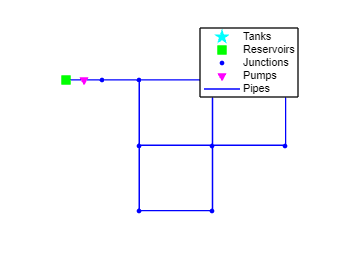

d.plot;

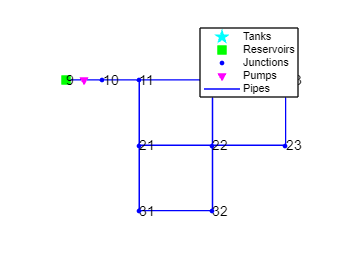

ans =   Axes with properties:

             XLim: [4 76]
             YLim: [2 98]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.13 0.11 0.775 0.815]
            Units: 'normalized'

  Show all properties


d.plot('nodes', 'yes', 'fontsize', 12)

d.plot('links', 'yes', 'fontsize', 12)

ans =   Axes with properties:

             XLim: [4 76]
             YLim: [2 98]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.13 0.11 0.775 0.815]
            Units: 'normalized'

  Show all properties


d.plot('linksindex', 'yes', 'fontsize',8);

d.plot('nodesindex', 'yes', 'fontsize',14);

d.plot('links', 'yes', 'highlightlink',{'10'}, 'fontsize',8);

d.plot('highlightnode',{'10', '32'});

d.plot('point', 'no');

d.plot('line', 'no');

linkSet1 = d.getLinkNameID(1:4);
colorLinkSet1 = repmat({'r'},1,length(linkSet1));
linkSet2 = d.getLinkNameID([5,6,7,8]);
colorLinkSet2=repmat({'g'},1,length(linkSet2));
d.plot('highlightlink',[linkSet1 linkSet2],'colorlink',[colorLinkSet1 colorLinkSet2])

ans =   Axes with properties:

             XLim: [4 76]
             YLim: [2 98]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.13 0.11 0.775 0.815]
            Units: 'normalized'

  Show all properties


d.plot('legend', 'hide')

ans =   Axes with properties:

             XLim: [4 76]
             YLim: [2 98]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.13 0.11 0.775 0.815]
            Units: 'normalized'

  Show all properties


d.plot('extend', 'yes')

ans =   Axes with properties:

             XLim: [4 76]
             YLim: [2 98]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0 0 1 1]
            Units: 'normalized'

  Show all properties


d.plot('legendposition', 'EastOutside')

ans =   Axes with properties:

             XLim: [4 76]
             YLim: [2 98]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.101988095646281 0.11 0.608005954814365 0.815]
            Units: 'normalized'

  Show all properties


h = figure;
d.plot('axes', h)

ans =   Axes with properties:

             XLim: [4 76]
             YLim: [2 98]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.13 0.11 0.775 0.815]
            Units: 'normalized'

  Show all properties


%Plot for matlab apps (GUIs)
%d.plot('uifigure', app.UIFigure, 'axes', app.UIAxes,'legend','hide');
h = d.plotGraph

h =   GraphPlot with properties:

     NodeColor: [0 0.447 0.741]
    MarkerSize: 4
        Marker: 'o'
     EdgeColor: [0 0.447 0.741]
     LineWidth: 0.5
     LineStyle: '-'
     NodeLabel: {'1'  '2'  '3'  '4'  '5'  '6'  '7'  '8'  '9'  '10'  '11'}
     EdgeLabel: {}
         XData: [0.911285794399768 0.35472963875954 0.344665988667186 0.159500276504298 -0.524510069903903 -0.557863727176631 -0.474828049437311 -1.31274016271899 -1.35519057269416 1.34133482543841 1.11361605816179]
         YData: [1.34178147214848 0.509315705923116 -0.481105763170841 -1.27841374610931 0.316655102797205 -0.479557757898093 -1.28258145508787 0.396353861389863 -0.23073209106568 1.98764247926404 -0.799357808190915]
         ZData: [0 0 0 0 0 0 0 0 0 0 0]

  Show 

title('Network Graph');

d.plotGraph('nodes', 'yes'); % Show ID of nodes
title('Network Graph with node IDs');

d.unload

EPANET Class is unloaded
